clear
clc

V0 = 0.895;
C1 = 38.72e-12;
Ron = 213;
Fs = 10E6;
VDD = 1.8;
Vth = 0.457;
Fin = 499/1024*Fs        

Fin = 4.8730e+06

% 以Fin = 0.5MHz 为目标
win = Fin * 2 * pi;


## Ron vs HD

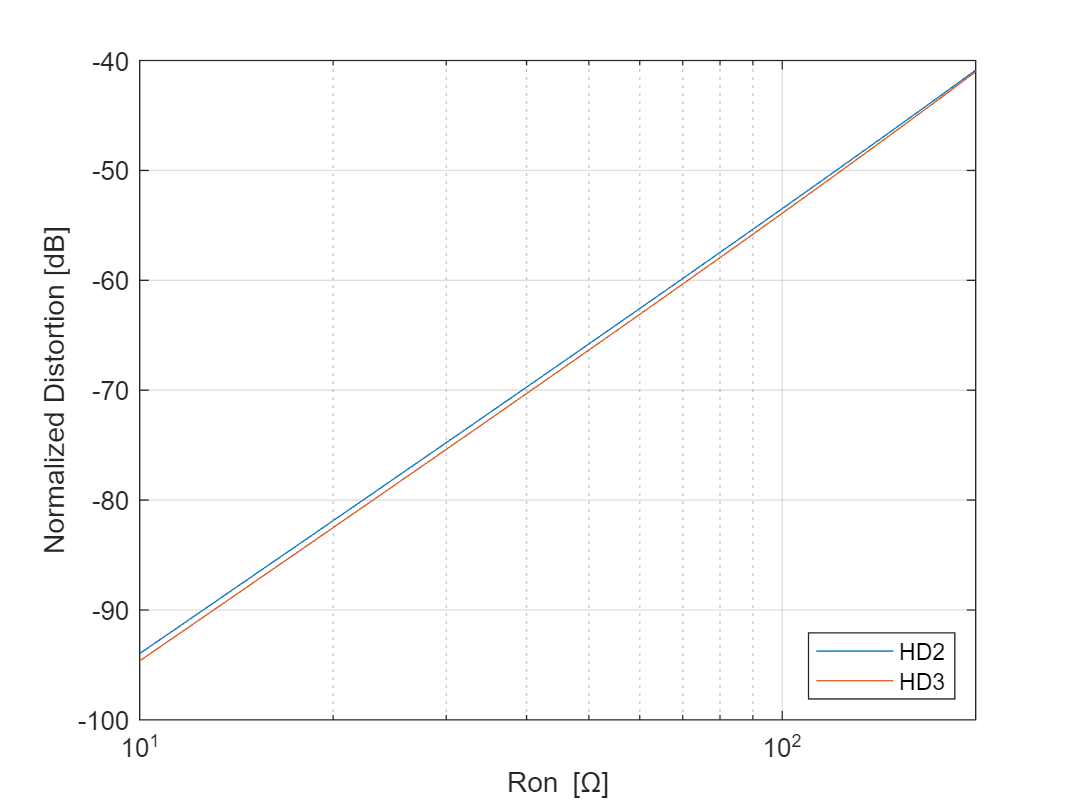

ron = linspace(10,200,100);
hd_ron = getHD_new(ron, V0, C1, Fin, -0.85);
figure
semilogx(ron, hd_ron);
% plot(log(ron), hd_ron);
grid on; box on;
xlabel("Ron [\Omega]");
ylabel("Normalized Distortion [dB]")
legend({'HD2', 'HD3'}, "Location","southeast")

% HD calculated by the linear equations of Ron;
% HD(dB) = K*log(Ron);
getHD_new(6.5, V0, C1, Fin, -0.85)

ans =  -101.4697 -102.1415


## Fin vs HD

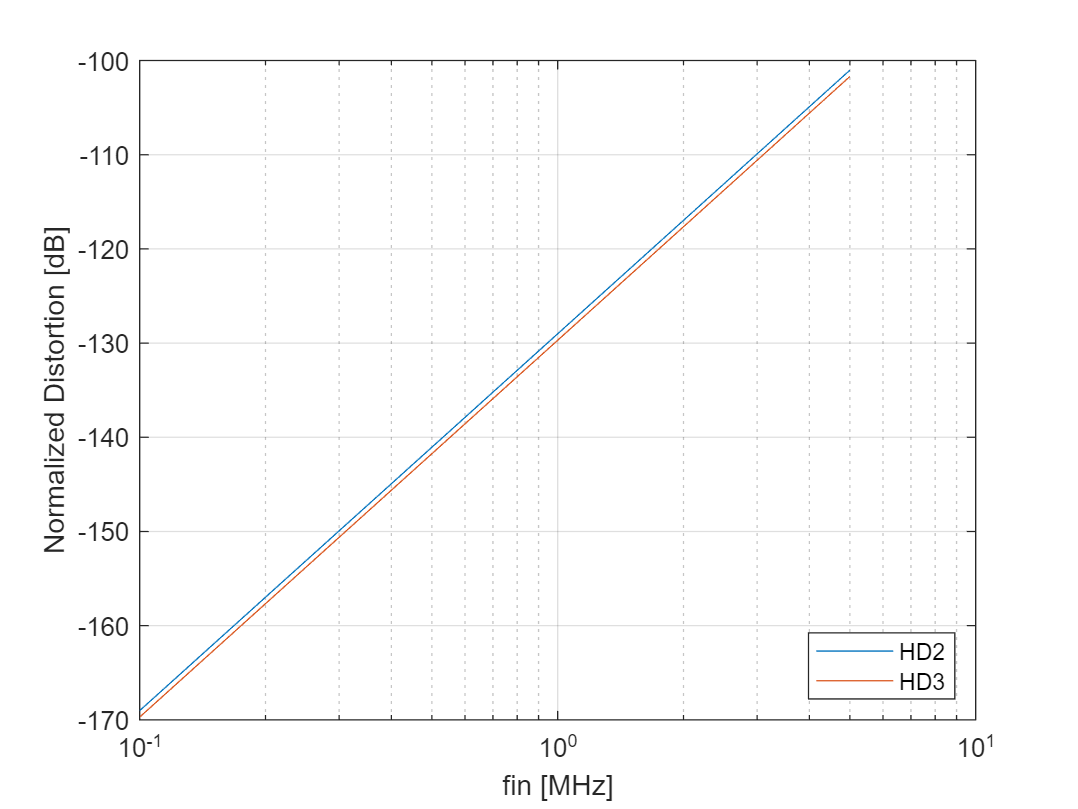

fin = linspace(0.01,0.5,100).*Fs;
hd_fin = getHD_new(6.5, V0, C1, fin, -0.85);
figure
semilogx(fin./(1E6), squeeze(hd_fin(1,:,:)));
grid on; box on;
xlabel("fin [MHz]");
ylabel("Normalized Distortion [dB]")
legend({'HD2', 'HD3'}, "Location","southeast")

% HD(dB) = K*log(fin);

## Fin & Ron vs HD

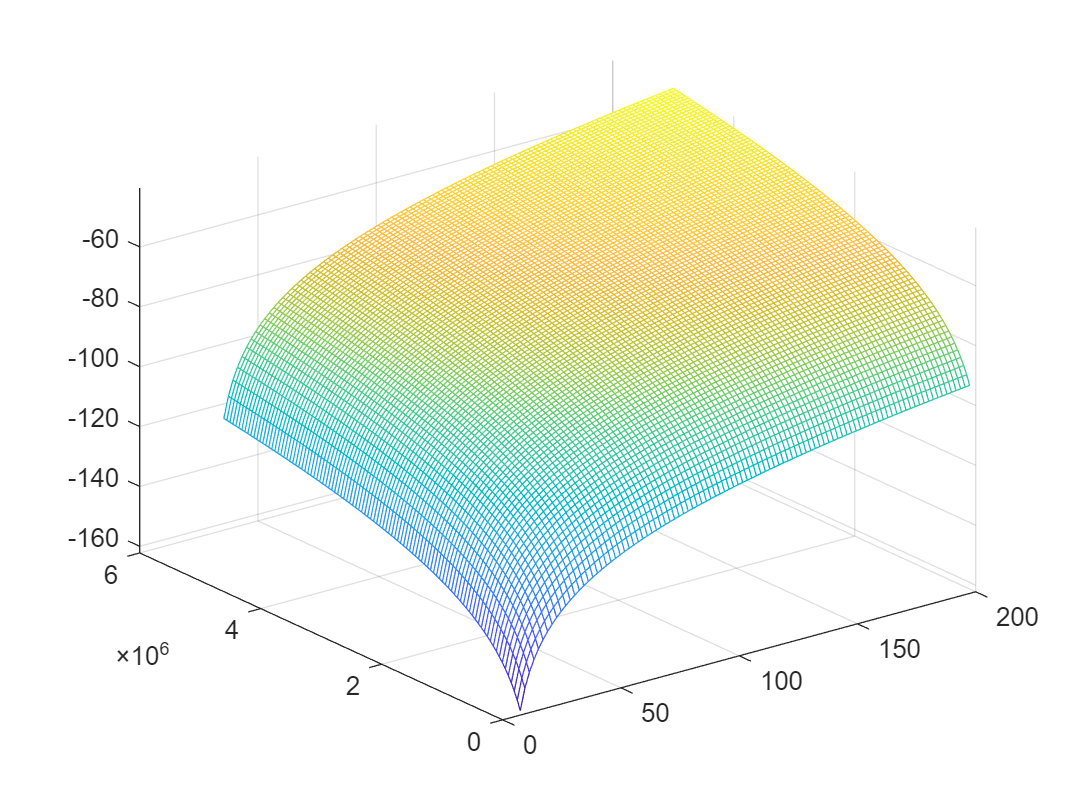

hd_tot = getHD_new(ron, V0, C1, fin, -0.85);
hd_tot3 = squeeze(hd_tot(:,2,:));
figure
mesh(ron, fin, hd_tot3)

% 三维图的结果并不明确，看不出有什么特别之处；

% For Fin = 500K, WL = 32*4u/4u, Ron = 100;
% Vdc_ideal: THD = 109dB;

